folder_where_RFTtoolbox_is_saved = 'C:/Users/qyc71/Documents/2022-2023 courses/Rotation winter/RFTtoolbox';
addpath(genpath(folder_where_RFTtoolbox_is_saved))

**1D**

Height distribution, lattice (resadd = 0) vs convolution (resadd = 10,6,3)

M = 1000; 
nvox = 1000; resadd = 10; xvals = 1:nvox;
FWHM = 3;

peak_y_vec = [];
peak_y_vec2 = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    % convolution
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    peak_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    peak_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec = [peak_y_vec, peak_y];
    % lattice
    resadd2 = 1;
    params = ConvFieldParams(FWHM, resadd2, 0);
    [cfielda, ss] = convfield(lat_data, params);
    cfielda.field = cfielda.field/sqrt(ss);
    peak_x = cfielda.xvals{1}(lmindices(cfielda.field,'all'));
    peak_y = transpose(cfielda.field(lmindices(cfielda.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec2 = [peak_y_vec2, peak_y];
end

resadd = 6;
peak_y_vec3 = [];
peak_y_vec4 = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    % convolution
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    peak_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    peak_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec3 = [peak_y_vec3, peak_y];
    % lattice
    resadd2 = 1;
    params = ConvFieldParams(FWHM, resadd2, 0);
    [cfielda, ss] = convfield(lat_data, params);
    cfielda.field = cfielda.field/sqrt(ss);
    peak_x = cfielda.xvals{1}(lmindices(cfielda.field,'all'));
    peak_y = transpose(cfielda.field(lmindices(cfielda.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec4 = [peak_y_vec4, peak_y];
end

resadd = 3;

peak_y_vec5 = [];
peak_y_vec6 = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    % convolution
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    peak_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    peak_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec5 = [peak_y_vec5, peak_y];
    % lattice
    resadd2 = 1;
    params = ConvFieldParams(FWHM, resadd2, 0);
    [cfielda, ss] = convfield(lat_data, params);
    cfielda.field = cfielda.field/sqrt(ss);
    peak_x = cfielda.xvals{1}(lmindices(cfielda.field,'all'));
    peak_y = transpose(cfielda.field(lmindices(cfielda.field, 'all')));
    if ismember(1,peak_x)
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_y_vec6 = [peak_y_vec6, peak_y];
end

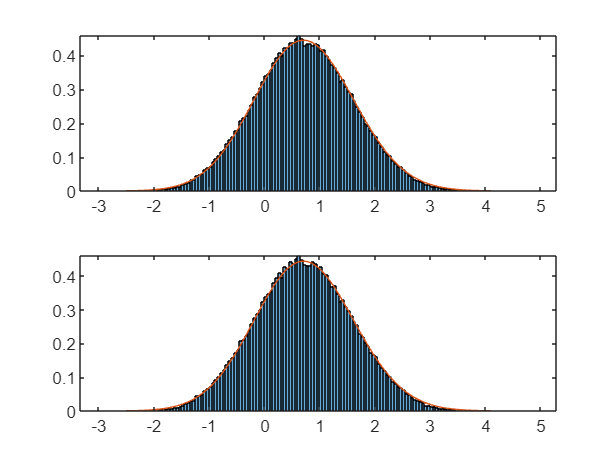

% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(peak_y_vec) + min(peak_y_vec);
thm_density = peak_thm_density(1, x, k);
% plots
tiledlayout(2,1)
nexttile
histogram(peak_y_vec, 'Normalization','pdf') % convolution filed
hold on
plot(x, thm_density)
nexttile
histogram(peak_y_vec2, 'Normalization','pdf') % lattice
hold on
plot(x, thm_density)

P-value

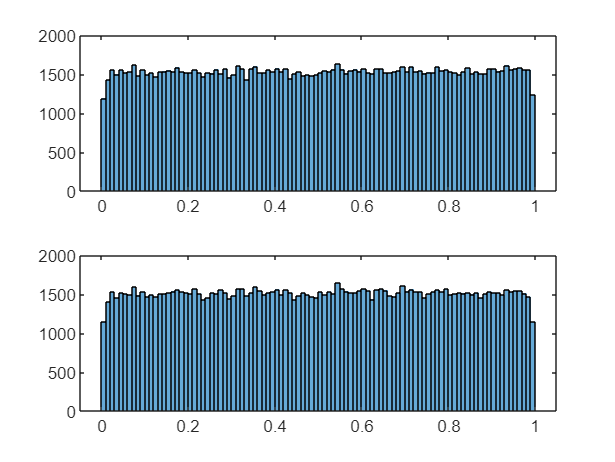

peak_y_cdf = peak_thm_cdf(1, peak_y_vec, k, -10);
peak_y_cdf2 = peak_thm_cdf(1, peak_y_vec2, k, -10);
tiledlayout(2,1)
nexttile
histogram(1-peak_y_cdf, 100)
nexttile
histogram(1-peak_y_cdf2, 100)


peak_y_cdf3 = peak_thm_cdf(1, peak_y_vec3, k, -10);
peak_y_cdf4 = peak_thm_cdf(1, peak_y_vec4, k, -10);
peak_y_cdf5 = peak_thm_cdf(1, peak_y_vec5, k, -10);
peak_y_cdf6 = peak_thm_cdf(1, peak_y_vec6, k, -10);

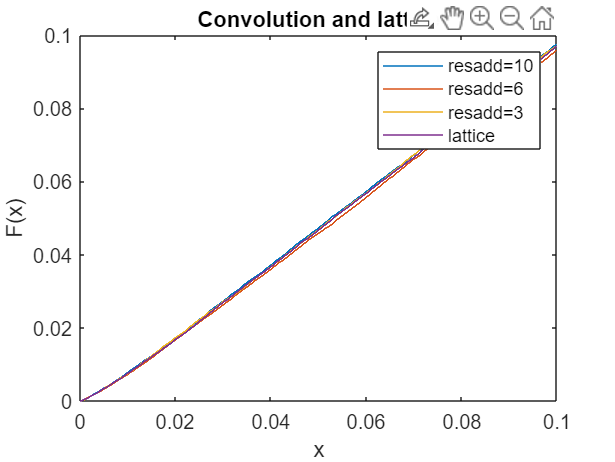


clf;
ecdf(1-peak_y_cdf); hold on;
ecdf(1-peak_y_cdf3);
ecdf(1-peak_y_cdf5);ecdf(1-peak_y_cdf2);
xlim([0,0.1])
legend('resadd=10','resadd=6','resadd=3','lattice');
title("Convolution and lattice")

hold off;

Overshoot distribution

pre-threshold v

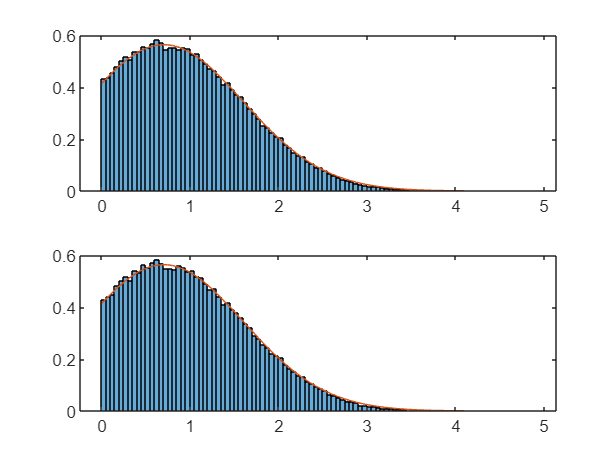

v = 0;
over_y_vec = peak_y_vec(peak_y_vec>v);
over_y_vec2 = peak_y_vec2(peak_y_vec2>v);
over_y_vec3 = peak_y_vec3(peak_y_vec3>v);
over_y_vec4 = peak_y_vec4(peak_y_vec4>v);
over_y_vec5 = peak_y_vec5(peak_y_vec5>v);
over_y_vec6 = peak_y_vec6(peak_y_vec6>v);
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(over_y_vec) + min(over_y_vec);
thm_density = peak_thm_density(1, x, k)/(1-peak_thm_cdf(1, v, k, -10));
% plots
tiledlayout(2,1)
nexttile
histogram(over_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)
nexttile
histogram(over_y_vec2, 'Normalization','pdf')
hold on
plot(x, thm_density)

P-value

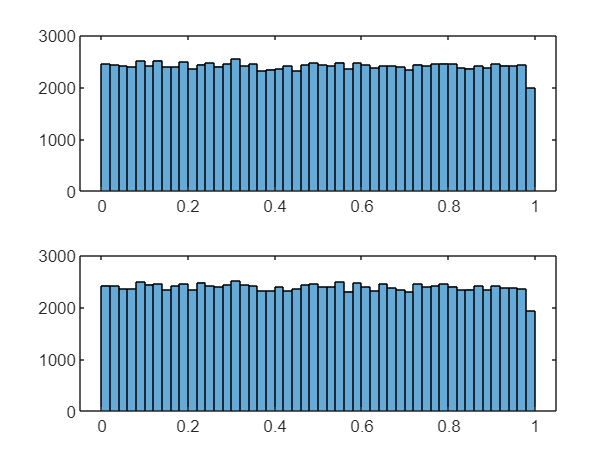

over_y_cdf = (1-peak_thm_cdf(1, over_y_vec, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
over_y_cdf2 = (1-peak_thm_cdf(1, over_y_vec2, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
over_y_cdf3 = (1-peak_thm_cdf(1, over_y_vec3, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
over_y_cdf4 = (1-peak_thm_cdf(1, over_y_vec4, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
over_y_cdf5 = (1-peak_thm_cdf(1, over_y_vec5, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
over_y_cdf6 = (1-peak_thm_cdf(1, over_y_vec6, k, -10))/...
    (1-peak_thm_cdf(1, v, k, -10));
tiledlayout(2,1)
nexttile
histogram(1-over_y_cdf)
nexttile
histogram(1-over_y_cdf2)

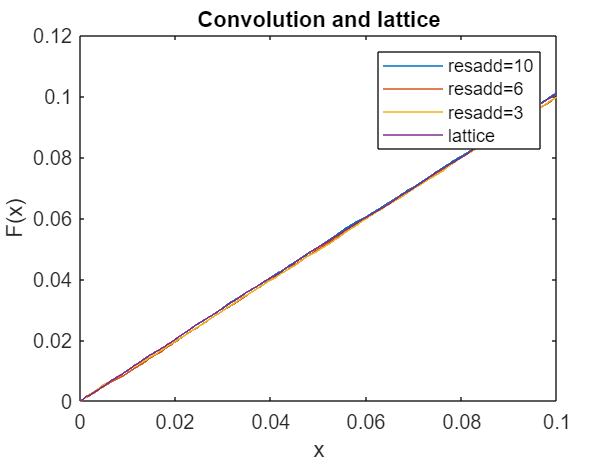

clf;
ecdf(1-over_y_cdf); hold on;
ecdf(1-over_y_cdf3);
ecdf(1-over_y_cdf5);
ecdf(1-over_y_cdf2);
xlim([0,0.1])
legend('resadd=10','resadd=6','resadd=3','lattice');
title("Convolution and lattice")
hold off;

v = 1;
over_y_vec = peak_y_vec(peak_y_vec>v);
over_y_vec2 = peak_y_vec2(peak_y_vec2>v);
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(over_y_vec) + min(over_y_vec);
thm_density = peak_thm_density(1, x, k)/(1-peak_thm_cdf(1, v, k, -10));
% plots
tiledlayout(2,1)
nexttile
histogram(over_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)
nexttile
histogram(over_y_vec2, 'Normalization','pdf')
hold on
plot(x, thm_density)

v = 2;
over_y_vec = peak_y_vec(peak_y_vec>v);
over_y_vec2 = peak_y_vec2(peak_y_vec2>v);
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(over_y_vec) + min(over_y_vec);
thm_density = peak_thm_density(1, x, k)/(1-peak_thm_cdf(1, v, k, -10));
% plots
tiledlayout(2,1)
nexttile
histogram(over_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)
nexttile
histogram(over_y_vec2, 'Normalization','pdf')
hold on
plot(x, thm_density)

**2D**

clf; M = 1000; 
Dim = [20,20]; D = length(Dim);
peak_y_c1 = [];
peak_y2_c1 = [];
peak_y_c2 = [];
peak_y2_c2 = [];
peak_y_c3 = [];
peak_y2_c3 = [];
for i = 1:M
    lat_data = wfield(Dim);
    %% case 1
    resadd = 4; FWHM = 2;
    % convolution
    params = ConvFieldParams([FWHM,FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y_c1 = [peak_y_c1;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
    % lattice
    params = ConvFieldParams([FWHM,FWHM], 0, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y2_c1 = [peak_y2_c1;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
    % case 2
    resadd = 6; FWHM = 2;
    % convolution
    params = ConvFieldParams([FWHM,FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y_c2 = [peak_y_c2;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
    % lattice
    params = ConvFieldParams([FWHM,FWHM], 0, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y2_c2 = [peak_y2_c2;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
    % case 3
    resadd = 8; FWHM = 2;
    % convolution
    params = ConvFieldParams([FWHM,FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y_c3 = [peak_y_c3;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
    % lattice
    params = ConvFieldParams([FWHM,FWHM], 0, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y2_c3 = [peak_y2_c3;...
            fine_data.field(temp(1, j), temp(2, j))];
        end  
    end
end



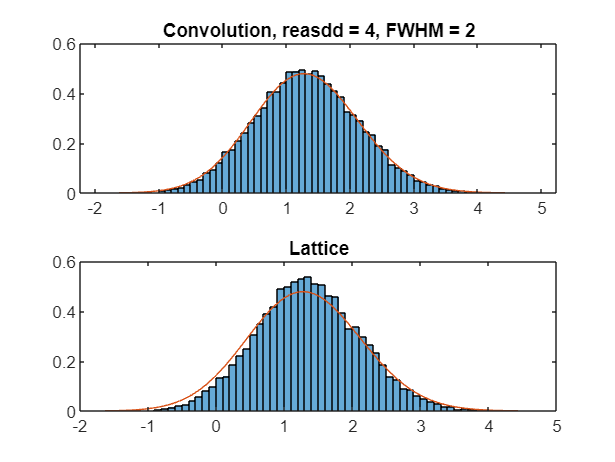

k = 1;
% case 1
x = (0:1000)/1000*range(peak_y_c1) + min(peak_y_c1);
thm_density = peak_thm_density(2, x, k);

% plots
tiledlayout(2,1)
nexttile
histogram(peak_y_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Convolution, reasdd = 4, FWHM = 2")
nexttile
histogram(peak_y2_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Lattice")

P-value

peak_y_cdf = peak_thm_cdf(2, peak_y_c1, k, -10);
peak_y_cdf2 = peak_thm_cdf(2, peak_y2_c1, k, -10);
peak_y_cdf3 = peak_thm_cdf(2, peak_y_c2, k, -10);
peak_y_cdf4 = peak_thm_cdf(2, peak_y2_c2, k, -10);
peak_y_cdf5 = peak_thm_cdf(2, peak_y_c3, k, -10);
peak_y_cdf6 = peak_thm_cdf(2, peak_y2_c3, k, -10);

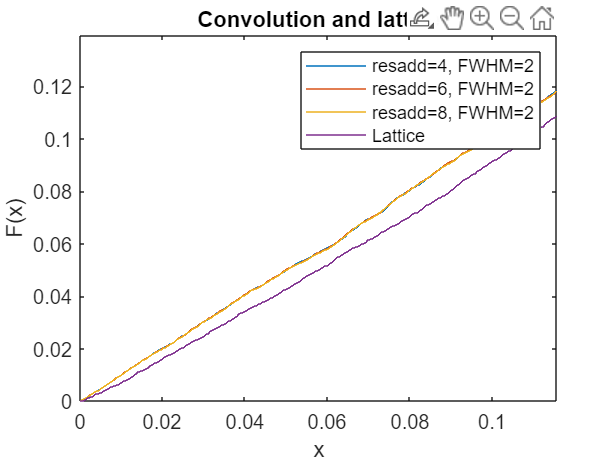

clf;
ecdf(1-peak_y_cdf);
xlim([0 0.1]);
hold on;
ecdf(1-peak_y_cdf3);
ecdf(1-peak_y_cdf5);
ecdf(1-peak_y_cdf2);
legend('resadd=4, FWHM=2','resadd=6, FWHM=2','resadd=8, FWHM=2',"Lattice");
title("Convolution and lattice")
hold off;

Overshoot distribution

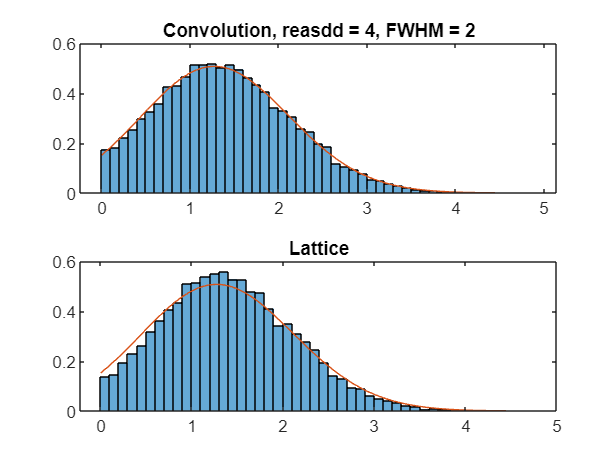

v = 0;
%% case 1
over_y_c1 = peak_y_c1(peak_y_c1>v);
over_y2_c1 = peak_y2_c1(peak_y2_c1>v);
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(over_y_c1) + min(over_y_c1);
thm_density = peak_thm_density(2, x, k)/(1-peak_thm_cdf(2, v, k, -10));
% plots
tiledlayout(2,1)
nexttile
histogram(over_y_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Convolution, reasdd = 4, FWHM = 2")
nexttile
histogram(over_y2_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Lattice")

P-value

v = 0;
over_y_c1 = peak_y_c1(peak_y_c1>v);
over_y2_c1 = peak_y2_c1(peak_y2_c1>v);
over_y_c2 = peak_y_c2(peak_y_c2>v);
over_y2_c2 = peak_y2_c2(peak_y2_c2>v);
over_y_c3 = peak_y_c3(peak_y_c3>v);
over_y2_c3 = peak_y2_c3(peak_y2_c3>v);
over_y_cdf = (1-peak_thm_cdf(2, over_y_c1, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));
over_y_cdf2 = (1-peak_thm_cdf(2, over_y2_c1, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));
over_y_cdf3 = (1-peak_thm_cdf(2, over_y_c2, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));
over_y_cdf4 = (1-peak_thm_cdf(2, over_y2_c2, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));
over_y_cdf5 = (1-peak_thm_cdf(2, over_y_c3, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));
over_y_cdf6 = (1-peak_thm_cdf(2, over_y2_c3, k, -10))/...
    (1-peak_thm_cdf(2, v, k, -10));

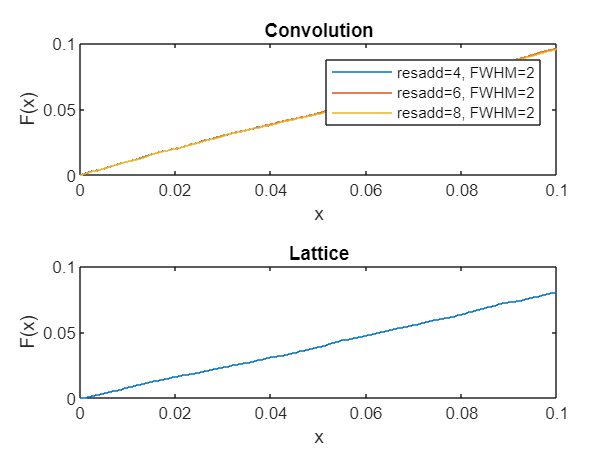


tiledlayout(2,1)
nexttile
ecdf(1-over_y_cdf);xlim([0 0.1]); hold on;
ecdf(1-over_y_cdf3);
ecdf(1-over_y_cdf5);
legend('resadd=4, FWHM=2','resadd=6, FWHM=2','resadd=8, FWHM=2');
title("Convolution")
hold off;
nexttile
ecdf(1-over_y_cdf2);xlim([0 0.1]); hold on;
title("Lattice")
hold off;

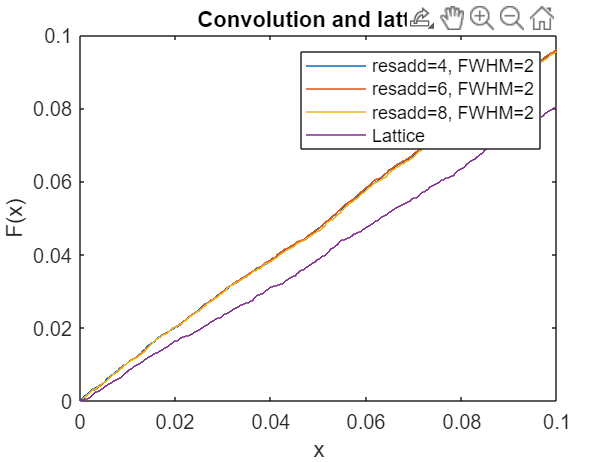

clf;
ecdf(1-over_y_cdf);xlim([0 0.1]); hold on;
ecdf(1-over_y_cdf3);
ecdf(1-over_y_cdf5);
ecdf(1-over_y_cdf2);xlim([0 0.1]);
legend('resadd=4, FWHM=2','resadd=6, FWHM=2','resadd=8, FWHM=2', "Lattice");
title("Convolution and lattice")
hold off;

**3D**

**resadd=1,3,5; fwhm=2**

clf; M = 1000; 
Dim = [20,20,20]; D = length(Dim); FWHM = 2;

peak_y_c1 = [];
peak_y2_c1 = [];
peak_y_c2 = [];
peak_y2_c2 = [];
peak_y_c3 = [];
peak_y2_c3 = [];
for i = 1:M
    lat_data = wfield(Dim);
    %% case 1
    % convolution
    resadd = 1;
    params = ConvFieldParams([FWHM,FWHM, FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(3,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1 && temp(3,j) ~= 1
            peak_y_c1 = [peak_y_c1;...
            fine_data.field(temp(1, j), temp(2, j), temp(3, j))];
        end  
    end
    % lattice
    resadd2 = 0;
    params = ConvFieldParams([FWHM,FWHM, FWHM], resadd2, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(3,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1 && temp(3,j) ~= 1
            peak_y2_c1 = [peak_y2_c1;...
            fine_data.field(temp(1, j), temp(2, j), temp(3, j))];
        end  
    end
    %% case 2
    % convolution
    resadd = 3;
    params = ConvFieldParams([FWHM,FWHM, FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(3,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1 && temp(3,j) ~= 1
            peak_y_c2 = [peak_y_c2;...
            fine_data.field(temp(1, j), temp(2, j), temp(3, j))];
        end  
    end
    %% case 3
    % convolution
    resadd = 5;
    params = ConvFieldParams([FWHM,FWHM, FWHM], resadd, 0);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(3,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1 && temp(3,j) ~= 1
            peak_y_c3 = [peak_y_c3;...
            fine_data.field(temp(1, j), temp(2, j), temp(3, j))];
        end  
    end

end

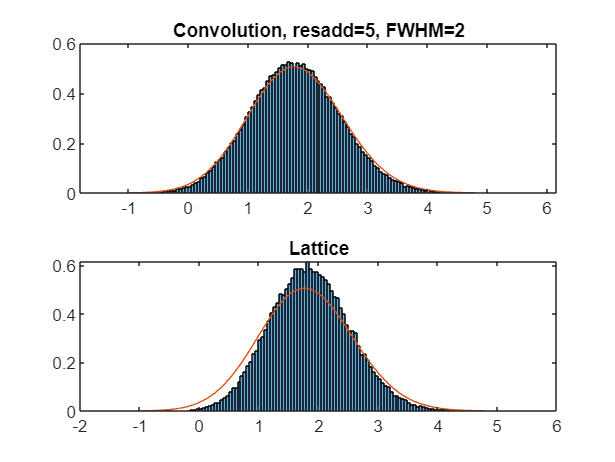

k = 1;
x = (0:1000)/1000*range(peak_y_c3) + min(peak_y_c3);
thm_density = peak_thm_density(3, transpose(x), k);

% plots
tiledlayout(2,1)
nexttile
histogram(peak_y_c3, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Convolution, resadd=5, FWHM=2")
nexttile
histogram(peak_y2_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Lattice")

P-value

peak_y_cdf = peak_thm_cdf(3, peak_y_c1, k, -5, 0.0001);
peak_y_cdf2 = peak_thm_cdf(3, peak_y2_c1, k, -5, 0.0001);
peak_y_cdf3 = peak_thm_cdf(3, peak_y_c2, k, -5, 0.0001);
peak_y_cdf5 = peak_thm_cdf(3, peak_y_c3, k, -5, 0.0001);

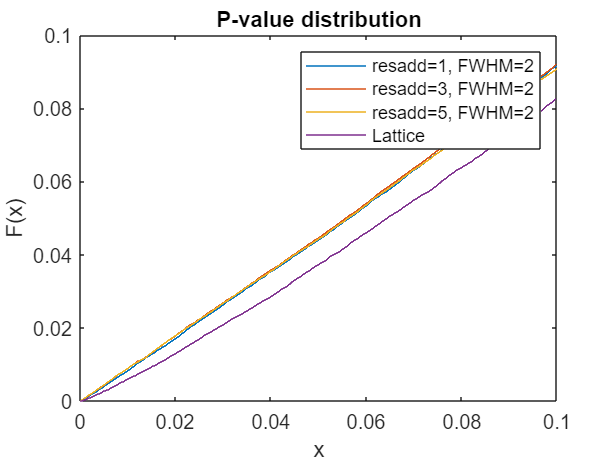

clf;
ecdf(1-peak_y_cdf);
xlim([0 0.1]);
hold on;
ecdf(1-peak_y_cdf3);
ecdf(1-peak_y_cdf5);
ecdf(1-peak_y_cdf2);
legend('resadd=1, FWHM=2','resadd=3, FWHM=2','resadd=5, FWHM=2',"Lattice");
title("P-value distribution")
hold off;

Overshoot distribution

pre-threshold v

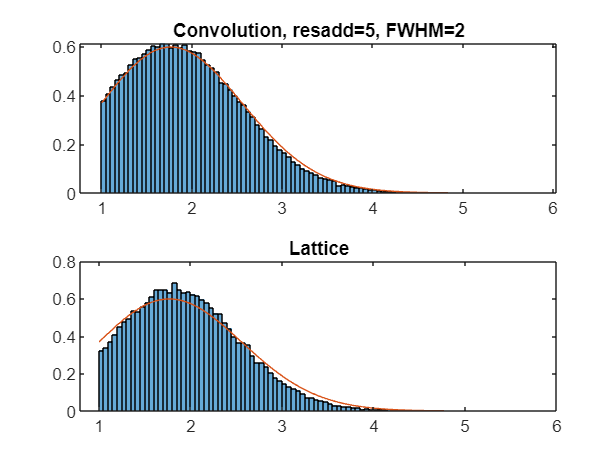

v = 1;
%% case 3
over_y_c3 = peak_y_c3(peak_y_c3>v);
over_y2_c1 = peak_y2_c1(peak_y2_c1>v);
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(over_y_c3) + min(over_y_c3);
thm_density = peak_thm_density(3, transpose(x), k)/(1-peak_thm_cdf(3, v, k, -5, 0.0001));
% plots
tiledlayout(2,1)
nexttile
histogram(over_y_c3, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Convolution, resadd=5, FWHM=2")
nexttile
histogram(over_y2_c1, 'Normalization','pdf')
hold on
plot(x, thm_density)
title("Lattice")

P-value

over_y_c1 = peak_y_c1(peak_y_c1>v);
over_y_c2 = peak_y_c2(peak_y_c2>v);


over_y_cdf = (1-peak_thm_cdf(3, over_y_c1, k, -5, 0.0001))/...
    (1-peak_thm_cdf(3, v, k, -5, 0.0001));
over_y_cdf2 = (1-peak_thm_cdf(3, over_y2_c1, k, -5, 0.0001))/...
    (1-peak_thm_cdf(3, v, k, -5, 0.0001));
over_y_cdf3 = (1-peak_thm_cdf(3, over_y_c2, k, -5, 0.0001))/...
    (1-peak_thm_cdf(3, v, k, -5, 0.0001));
over_y_cdf5 = (1-peak_thm_cdf(3, over_y_c3, k, -5, 0.0001))/...
    (1-peak_thm_cdf(3, v, k, -5, 0.0001));

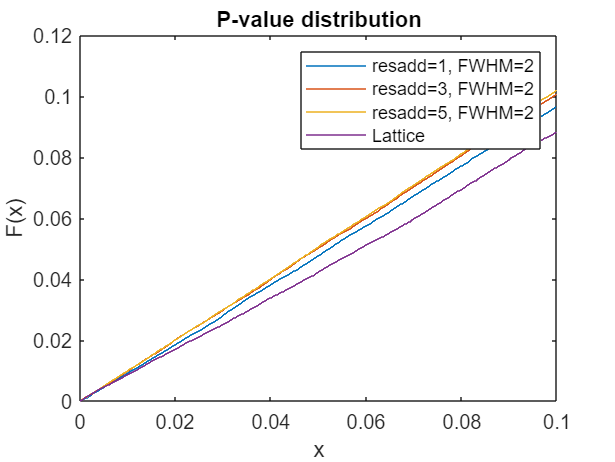

clf;
ecdf(1-over_y_cdf);xlim([0 0.1]); hold on;
ecdf(1-over_y_cdf3);
ecdf(1-over_y_cdf5);
ecdf(1-over_y_cdf2);xlim([0 0.1]);
legend('resadd=1, FWHM=2','resadd=3, FWHM=2','resadd=5, FWHM=2', "Lattice");
title("P-value distribution")
hold off;